# Exactly solvable NLS example with nonhomogeneous vertex conditions

Consider the cubic nonlinear Schrodinger equation


$$i u_t = -\triangle u + |u|^2 u$$


on a lollipop graph defined as follows

## Set up the Graph

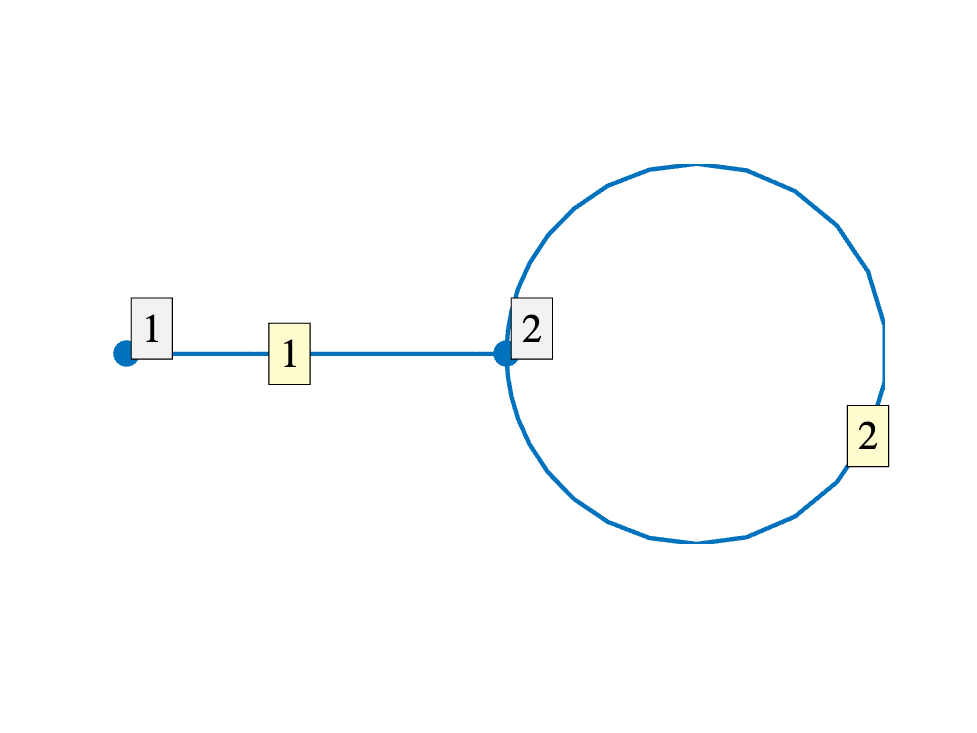

LVec=[2 2*pi];
nX=32;
rbc=[nan 1];
Phi=quantumGraphFromTemplate('multibell','nBells',1,...
           'LVec',LVec,'nX',nX,'robinCoeff',rbc,'Discretization','Chebyshev');
Phi.plot('layout')

subject to vertex conditions


$$\left. u \right|_{v_1} = e^{-2it}\\
-u_1'(2) + u_2'(0)-u_2'(2\pi) + u_1(2) = (1-i) e^{-2it}$$


This has exact solution 


$$\left.u\right|_{e_1}  =e^{i(x-2-2t)\\
\left.u\right|_{e_2}  =e^{i(x-2t)$$


## Now set up and run initial value problem

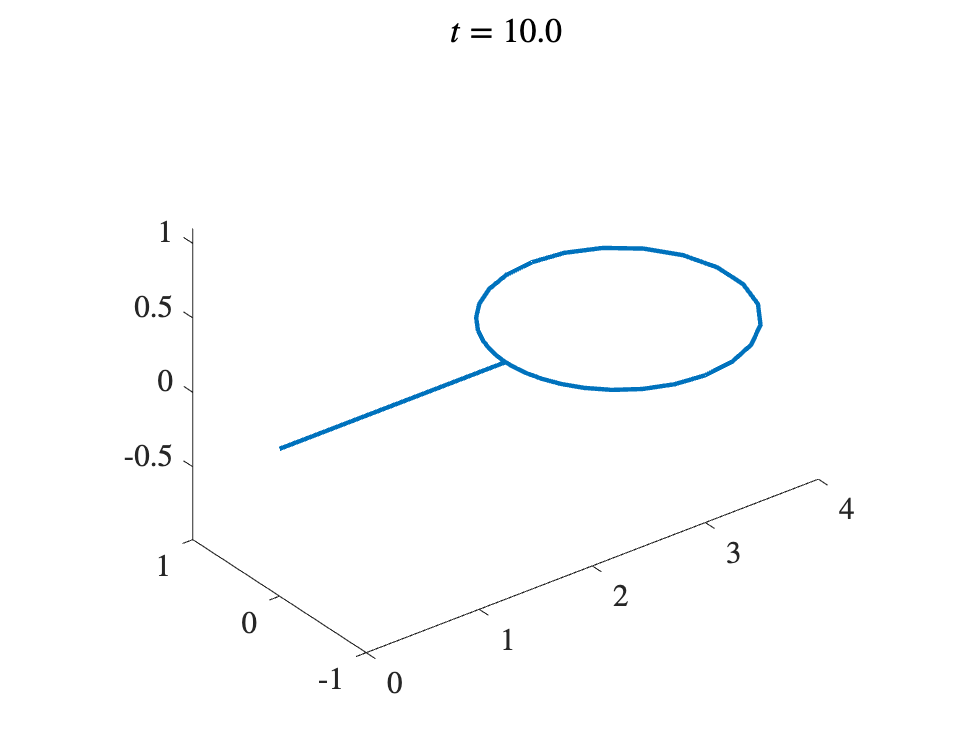

u0=Phi.applyFunctionsToAllEdges({@(x)exp(1i*(x-2)),@(x)exp(1i*x)});
phiNode=@(t)[exp(-2i); 1-1i]*exp(-2i*t);
mu = 1i;
F=@(z) -1i * z.^2 .* conj(z);
tFinal = 10;
dt=0.1;
[t,u] = Phi.qgdeSDIRK443(mu,F,tFinal,u0,dt);
animatePDESolution(Phi,real(u),t);

## Plot the error at the final time

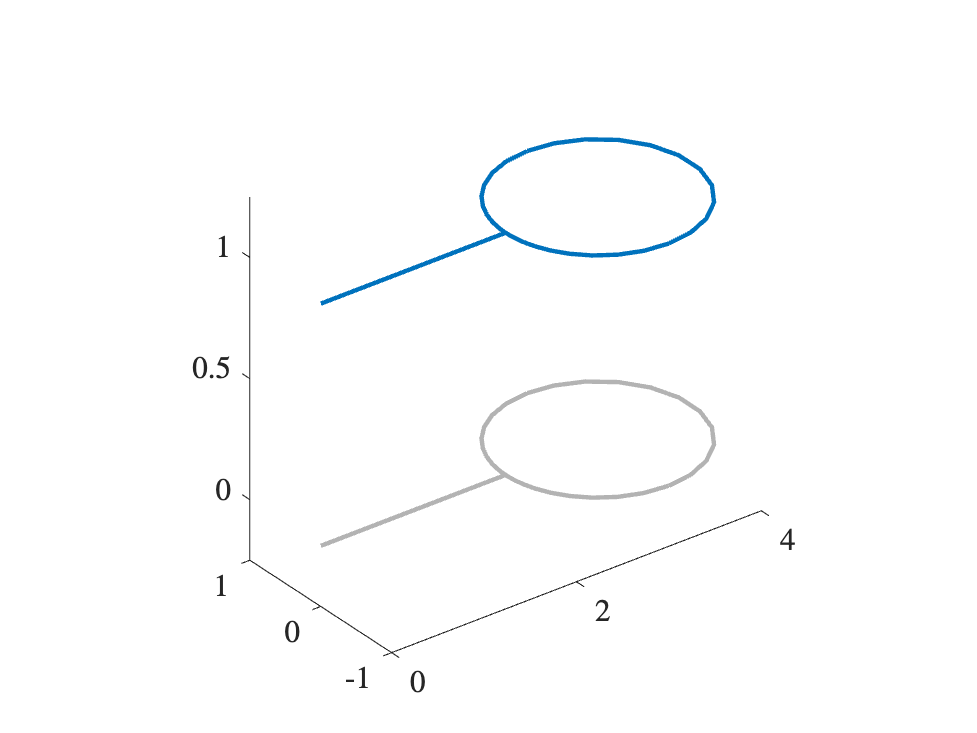

uexactFinal=u0*exp(-2i*tFinal);
Phi.plot(abs(u(:,end)-uexactFinal))